# 1: Prequel

Set the same paths/file as in step 1

% Main data folders (the same as in step 1)
clear
% where you stored the downloaded example data
datafolder = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];
% where you store the output
outfolder = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData\outfolder'];
mkdir(outfolder);

% load the goodunits
load(strcat(outfolder,'\goodunits.mat'));

# 2: Correlation of pre and post blood vessel images 

The Matlab Control Point Selection Tool enables you to pick control points in the image to be registered (the moving image) and the reference image (the fixed image). I used CPselect to align the pre imaged bloodvessels (see Methods in the paper) with the post imaged bloodvessels thus generating a transformation matrix for the GFP image. That transformed GFP image can be aligned with the MEA grid and spike locations can be correlated with the GFP signals. Unfortunatly. this step is highly specific for Matlab users. But it might be possible to use another, freely availble package to register images with each other.


fixed = imread(strcat(datafolder,'\images\preBVs.png')); %reference image, cropped to MEA active area
moving = imread(strcat(datafolder,'\images\postBV.png')); % the post imaged BVs
C3 = imread(strcat(datafolder,'\images\GFP.png')); 
C4 = imread(strcat(datafolder,'\images\FOXP2.png')); % optional
C5 = imread(strcat(datafolder,'\images\SATB2.png')); % optional

#### DIY

The next step takes a long time...you can try or move to the next part and load existing transformation grids. 

cpselect(moving,fixed)
% you may want to save your moving and fixed points at some point

#### Load pre-existing data

load pre-existing transformation grids done by me

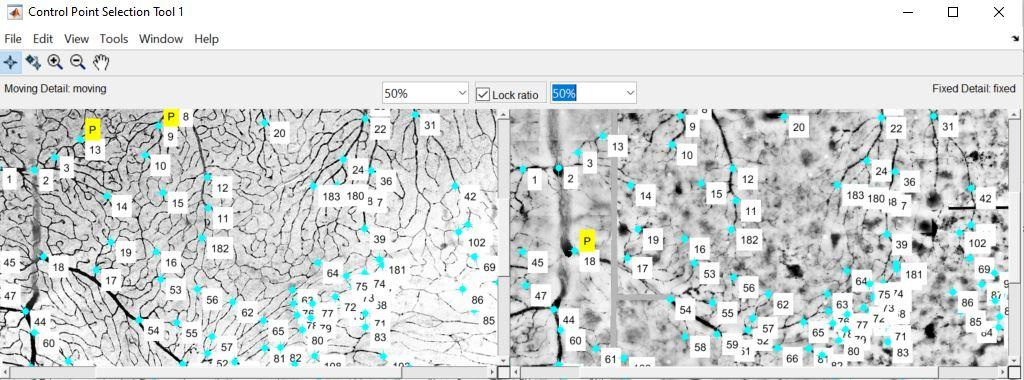

% Load a MAT-file that contains preselected control points for the fixed and moving images 
% and create a geometric transformation fit to the control points, using fitgeotrans.
load(strcat(datafolder,'\images\alignedImagedata.mat'));
tform = fitgeotrans(movingPoints,fixedPoints,'lwm',50);
% sometimes in streteched images
% tform = fitgeotrans(movingPoints,fixedPoints,'nonreflectivesimilarity');

Rfixed = imref2d(size(fixed));% Reference 2-D image to world coordinates

% warp the images to register with fixed image
registered1 = imwarp(moving,tform,'FillValues', 255,'OutputView',Rfixed);
IHC_BV_aligned = registered1;
imwrite(IHC_BV_aligned,strcat(outfolder,'\IHC-BV-aligned.png'))
% uncomment to display the overlay
% figure, imshowpair(fixed,registered1,'blend');

%register other images
registered2 = imwarp(C3,tform,'FillValues', 255,'OutputView',Rfixed);
registered3 = imwarp(C4,tform,'FillValues', 255,'OutputView',Rfixed);
registered4 = imwarp(C5,tform,'FillValues', 255,'OutputView',Rfixed);
IHC_C3_aligned = registered2;
imwrite(IHC_C3_aligned,strcat(outfolder,'\IHC-C3-aligned.png'))
IHC_C4_aligned = registered3;
imwrite(IHC_C4_aligned,strcat(outfolder,'\IHC-C4-aligned.png'))
IHC_C5_aligned = registered4;
imwrite(IHC_C5_aligned,strcat(outfolder,'\IHC-C5-aligned.png'))

save(strcat(outfolder,'\IHCdata.mat'),'IHC_BV_aligned', 'IHC_C3_aligned', 'IHC_C4_aligned', 'IHC_C5_aligned')

# 3: Aligning spikes and cells

clearvars -except outfolder datafolder

load(strcat(outfolder,'\goodunits.mat'));
load(strcat(outfolder,'\IHCdata.mat'));
GFP = IHC_C3_aligned;

#### A: Orientation

A crucial first step is to align your spike locations with the GFP cells. Since the x,y location of spikes is different than the imaged x,y location from cells, it is nessary to rotate and flip the GFP image to match with the spike location outline. There is no formula or guide for that since every MEA/Experiment/dataformat is slightly different. This part needs some time and should be adjusted for the system used - we used a 3Brain Biocam

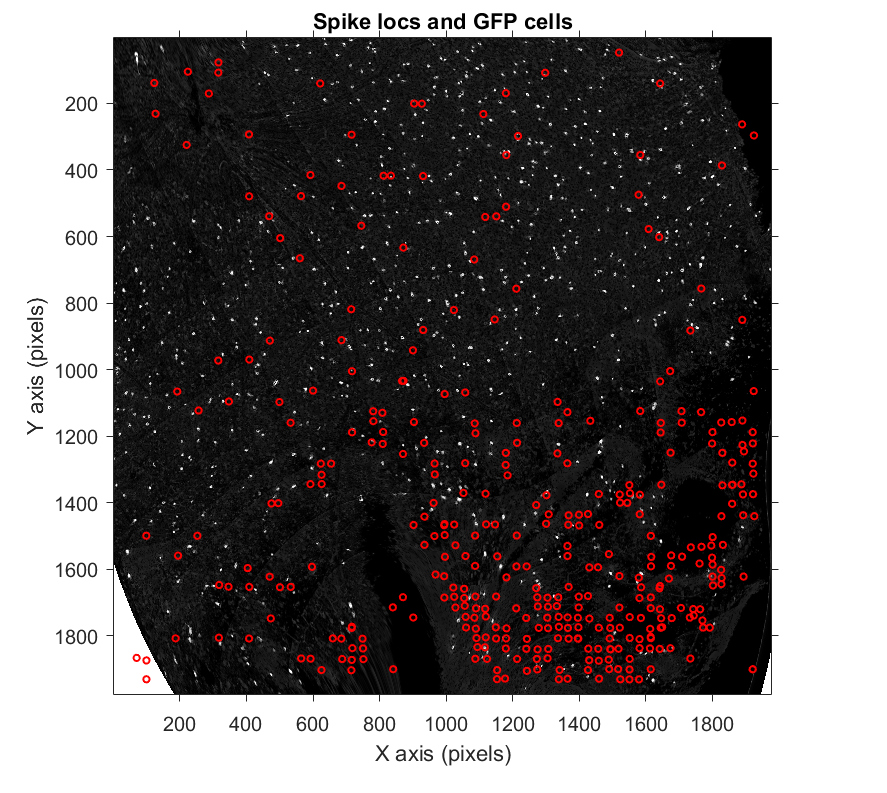

% align IHC orientation with data orientation (change irot and rotval)
irot = 0;
rotval=irot*pi/4;
GFPaligned=(rot90(imresize(GFP,[max(size(GFP)) max(size(GFP))]),irot)); % to do the trick, can use flipud too
C4aligned=(rot90(imresize(IHC_C4_aligned,[max(size(GFP)) max(size(GFP))]),irot)); % optional
C5aligned=(rot90(imresize(IHC_C5_aligned,[max(size(GFP)) max(size(GFP))]),irot)); % optional
% scale factor to match the image size with the MEA size (adjust the size)
sf=max(size(GFPaligned))/64; % 64 is number of electrodes per axis - we cropped the BV images to a 64 x 64 electrode grid 

clearvars spikelocs_IM
cmbdata_locs =cell2mat(goodunits(2:3,:));
spikelocs_IM(1,:) = (cmbdata_locs(1,:)*sf)+sf/2; % the exapnsion factor to match spikes with image
spikelocs_IM(2,:) = (cmbdata_locs(2,:)*sf)+sf/2; % + sf/2 is because the electrodes are big squares (21 microns square)


% plot the spike locs and cells
imshow(GFPaligned(:,:,2),[])
hold on
for i = 1:length(spikelocs_IM(1,:))
    scatter(spikelocs_IM(1,:),spikelocs_IM(2,:),10,'o','r','LineWidth',1)
    hold on
end

save(strcat(outfolder,'\','IHCaligned_data','.mat'),'GFPaligned','irot',...
    'C4aligned','C5aligned','spikelocs_IM','sf','rotval');
axis on
axis square
xlabel('X axis (pixels)')
ylabel('Y axis (pixels)')
title('Spike locs and GFP cells')



disp('done testing orientation')

done testing orientation


#### B: GFP segmentation

The last step gave us the spike location in pixel units. But we are lacking the GFP cell location in pixel units to progress. Here, I use a simple but effective segmentation and a blob detection to get the centres of the GFP cells.

You need this: Fatma Gargouri (2021). thresholding the maximum entropy (https://www.mathworks.com/matlabcentral/fileexchange/35158-thresholding-the-maximum-entropy), MATLAB Central File Exchange. Retrieved September 21, 2021.

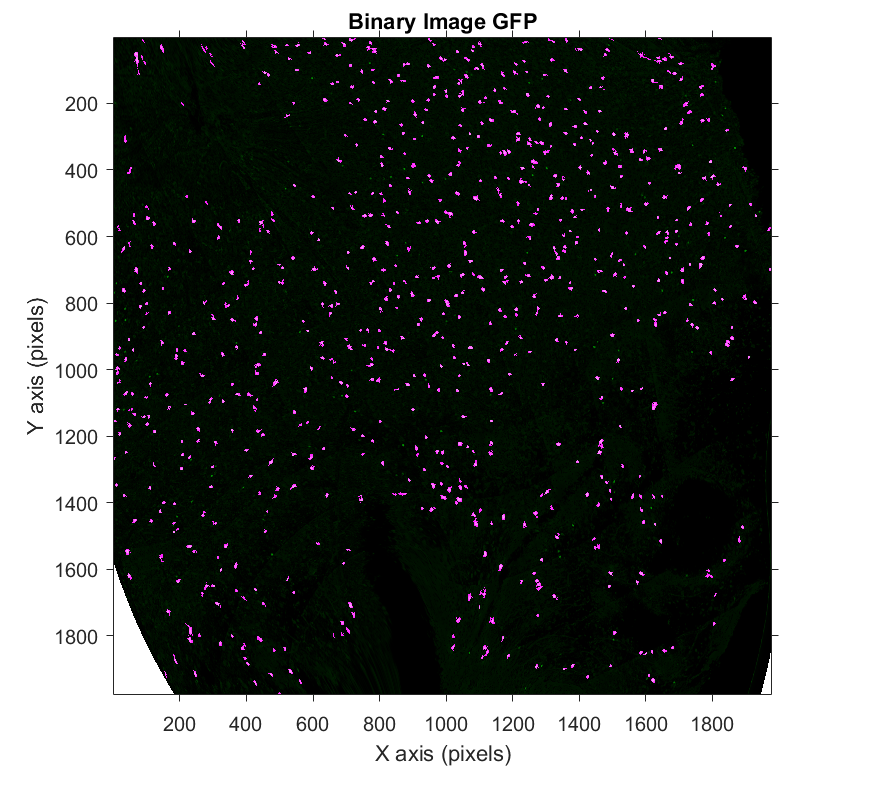

clearvars -except outfolder datafolder
load(strcat(outfolder,'\IHCaligned_data.mat'));

% make binary image
clearvars originalImage_GFP binaryImage_GFP
originalImage_GFP = GFPaligned(:,:,2);
thresholdValue = maxentropie(originalImage_GFP); % maxentropie from Gargouri 2021
binaryImage_GFP = originalImage_GFP > 1.0*thresholdValue; % change 1.0 when image is noisy
binaryImage_GFP = imfill(binaryImage_GFP, 'holes'); % nobody likes holes in the cells
binaryImage_GFP = bwareaopen(binaryImage_GFP, 50); % adjust 50 for best results - depends on pixel size of image
imshowpair(GFPaligned, binaryImage_GFP,'falsecolor')
axis on
axis square
xlabel('X axis (pixels)')
ylabel('Y axis (pixels)')
title('Binary Image GFP')


% blob detection
clearvars blobMeasurements_GFP boundaries_GFP
blobMeasurements_GFP = regionprops(binaryImage_GFP,originalImage_GFP,...
    'Centroid','EquivDiameter', 'MeanIntensity'); % the only things we need
boundaries_GFP = bwboundaries(binaryImage_GFP);

save(strcat(outfolder,'\','GFPblob_data','.mat'),'blobMeasurements_GFP','boundaries_GFP',...
    'binaryImage_GFP');

disp('done blob detection')

done blob detection


#### C: Approximation

Finding spike locs that are near GFP cells is the goal. Finding a good "near" threshold is a bit tricky. We know that spike locations are **not** always near the soma (Fried et al., 2009 doi: [10.1152/jn.91081.2008](https://dx.doi.org/10.1152%2Fjn.91081.2008) and Scott et al., 2014  [http://dx.doi.org/10.1038/ncomms4817](http://dx.doi.org/10.1038/ncomms4817) ). The spike initiation zone can be a little bit away from somas between 20-40 microns on average (for details see the papers). To overcome that obstacle, I looked for isolated GFP cells and looked the spike locs up that showend an alteration of spiking and/or bursting (see step 1 goodunits). Initially, I selected two zones - 30 and 60 microns. 30 is the middle of 20-40 microns from the literature and 60 is simply the double. The ratio for 60 microns is that there are cells in the papers that were more than 20 -40 micromns away - I wanted a zone for "outliers". However, I realised after running the entire analyse pipeline that the cells in both zones were more or less identical, in terms of classification to light responses. Hence, I pooled them for simplicity. Here, I will make that clear. 

clearvars -except outfolder datafolder
load(strcat(outfolder,'\IHCaligned_data.mat'));
load(strcat(outfolder,'\goodunits.mat'));
load(strcat(outfolder,'\GFPblob_data.mat'));

% 2670 is the length of Biocam 64 x 64 electrode grid in microns
microms2pixel = max(size(GFPaligned))/2670; % here 1 px = 0.7404 microns 

arbitraryDistance1 = round(30/microms2pixel); % zone 1 - 30 microns (see text)
arbitraryDistance2 = round(60/microms2pixel); %zone 2 - 60 microns
% pre allocation
numberOfBlobs = size(blobMeasurements_GFP, 1);
blobstats(1:numberOfBlobs,1:7) = {zeros};


for x1 = 1:numberOfBlobs
    blobstats{x1,1} = blobMeasurements_GFP(x1).Centroid(1);
    blobstats{x1,2} = blobMeasurements_GFP(x1).Centroid(2);
    % find all spike locs in zone 1
    clearvars xidx yidx midx
    xidx = find(spikelocs_IM(1,:)< (blobstats{x1,1}+arbitraryDistance1) & spikelocs_IM(1,:)> (blobstats{x1,1}-arbitraryDistance1));
    yidx = find(spikelocs_IM(2,:)< (blobstats{x1,2}+arbitraryDistance1) & spikelocs_IM(2,:)> (blobstats{x1,2}-arbitraryDistance1));
    midx = intersect(xidx,yidx);
    if isempty(midx)==1 % if there are no spike locs, look in zone 2
        clearvars xidx yidx midx
        xidx = find(spikelocs_IM(1,:)< (blobstats{x1,1}+arbitraryDistance2) & spikelocs_IM(1,:)> (blobstats{x1,1}-arbitraryDistance2));
        yidx = find(spikelocs_IM(2,:)< (blobstats{x1,2}+arbitraryDistance2) & spikelocs_IM(2,:)> (blobstats{x1,2}-arbitraryDistance2));
        midx = intersect(xidx,yidx);
        if isempty(midx)==1 % if there are no spike locs at all
            blobstats{x1,3} =-1; % condition -1 means no near spike locs

        else  % if there are spike locs in zone 2
            clearvars tmp
            for x2 = 1:length(midx)
                clearvars I
                % calculate the pairwise (Euclidian) distance between GFP
                % cell and spike locs
                tmp(1,x2) = pdist([blobstats{x1,1:2};spikelocs_IM(1,midx(x2)),spikelocs_IM(2,midx(x2))]);
                [~,I] = sort(tmp,'ascend'); % sort closest spike locs
                blobstats{x1,3} =2; % condition 2 - spikes in zone 2
                blobstats{x1,4} =cell2mat(goodunits(4,midx(I))); % unit IDs
                blobstats{x1,5} =spikelocs_IM(1,midx(I));
                blobstats{x1,6} =spikelocs_IM(2,midx(I));
                blobstats{x1,7} =tmp(1,I)*microms2pixel;
            end
        end
    else 
        clearvars tmp
        for x2 = 1:length(midx)
            tmp(1,x2) = pdist([blobstats{x1,1:2};spikelocs_IM(1,midx(x2)),spikelocs_IM(2,midx(x2))]);
            clearvars I
            [~,I] = min(tmp(1,:));
            blobstats{x1,3} =1; % condition 1 - spikes in zone 1
            blobstats{x1,4} =cell2mat(goodunits(4,midx(I))); % unit ID
            blobstats{x1,5} =spikelocs_IM(1,midx(I));
            blobstats{x1,6} =spikelocs_IM(2,midx(I));
            blobstats{x1,7} =tmp(1,I)*microms2pixel;
                
        end
    end
end

% blobstats(:,7) =round(blobstats(:,7)*microms2pixel);
blobstats_legend = {'blob x', 'blob y', 'condition', 'clus_id','spike x','spike y','distance microns'};
save(strcat(outfolder,'\','blobstats.mat'),'blobstats','blobstats_legend','numberOfBlobs');

disp('done approximation ')

done approximation 


# 4: Distance vs change of firing/bursting 

In theory, the DREADD unit found in zone 1 (or zone 2) should show some kind of change of their spike firing/bursting after exposure to CNO. Next, I will test that and plot the pairwise distance vs change of firing/bursting of all found units & spike locs. 

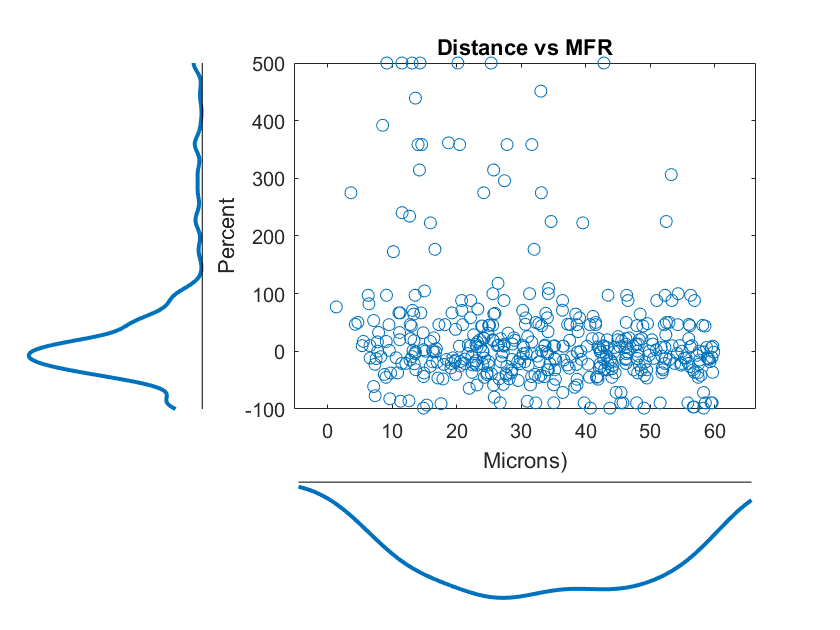

clearvars -except outfolder datafolder
load(strcat(outfolder,'\goodunits.mat'));
load(strcat(outfolder,'\blobstats.mat'));

% get the firing/burst change
ClusID = cell2mat(goodunits(4,:));
meanFRchange = cell2mat(goodunits(7,:));
medFRchange = cell2mat(goodunits(10,:));
BIchange = cell2mat(goodunits(13,:));
baseline = cell2mat(goodunits(5,:));

approxdata(1:length(cell2mat(blobstats(:,1))),1:11) =zeros;

% get the distance data for each unit
clearvars approxdata approxdata_legend

approxdata_legend{1,1} ='blob index';
approxdata_legend{1,2} ='blob x';
approxdata_legend{1,3} ='blob y';
approxdata_legend{1,4} ='clus_id';
approxdata_legend{1,5} ='clus x';
approxdata_legend{1,6} ='clus y';
approxdata_legend{1,7} ='distance microns';
approxdata_legend{1,8} ='meanFRchange';
approxdata_legend{1,9} ='medFRchange';
approxdata_legend{1,10} ='BIchange';
approxdata_legend{1,11} ='baseline';

k=1;
for i = 1:length(blobstats)
    clearvars tmp1 tmp2 tmp3 tmp4 tmp5 tmp6 
    tmp1 = cell2mat(blobstats(i,1)); % blob x
    tmp2 = cell2mat(blobstats(i,2)); % blob y
    tmp3 = cell2mat(blobstats(i,4)); % clus id
    tmp4 = cell2mat(blobstats(i,5)); % clus x
    tmp5 = cell2mat(blobstats(i,6)); % clus y
    tmp6 = cell2mat(blobstats(i,7)); % distance
    
    for ii = 1:length(tmp1)
        approxdata(k,1) = i; % blob id
        approxdata(k,2) = tmp1(ii); % blob x
        approxdata(k,3) = tmp2(ii); % blob y
        approxdata(k,4) = tmp3(ii); % clus id
        approxdata(k,5) = tmp4(ii); % clus x
        approxdata(k,6) = tmp5(ii); % clus y
        approxdata(k,7) = tmp6(ii); % distance
        k=k+1;
    end
end

for i = 1:length(approxdata)
    clearvars idx
    idx = find(ClusID==approxdata(i,4));
    approxdata(i,8) = meanFRchange(idx);
    approxdata(i,9) = medFRchange(idx);
    approxdata(i,10) = BIchange(idx);
    approxdata(i,11) = baseline(idx);
    if approxdata(i,4)==0
        approxdata(i,8) = 0;
        approxdata(i,9) = 0;
        approxdata(i,10) = 0;
        approxdata(i,11) = 0;
    end
end

% a bit of cleaning is needed
% The Euclidian distance can exceed 60 microns (see above) and hence is capped here at 60 microns
approxdata((approxdata(:,7)>60),:)=[]; 
approxdata((approxdata(:,11)<0.01),:)=[]; % min spike rate - get bad cells out
approxdata((approxdata(:,11)>30),:)=[]; % max spike rate - get bad cells out
approxdata((approxdata(:,8)>500),8)=500; % quench data within -100 and 500
approxdata((approxdata(:,9)>500),9)=500; % quench data within -100 and 500
approxdata((approxdata(:,10)>500),10)=500; % quench data within -100 and 500

% distance vs meanFRchange
scatterhist(approxdata(:,7),approxdata(:,8), 'Kernel', 'on', 'Direction','out')
ylim([-100 500]);
% xlim([0 60])
xlabel('Microns)')
ylabel('Percent')
title('Distance vs MFR')

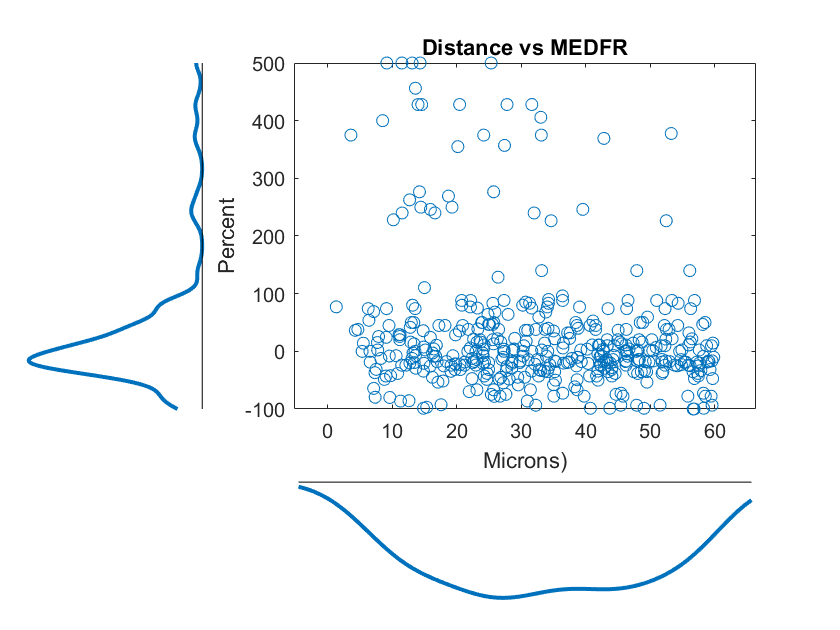


% distance vs medFRchange
scatterhist(approxdata(:,7),approxdata(:,9), 'Kernel', 'on', 'Direction','out')
ylim([-100 500]);
% xlim([0 60])
xlabel('Microns)')
ylabel('Percent')
title('Distance vs MEDFR')

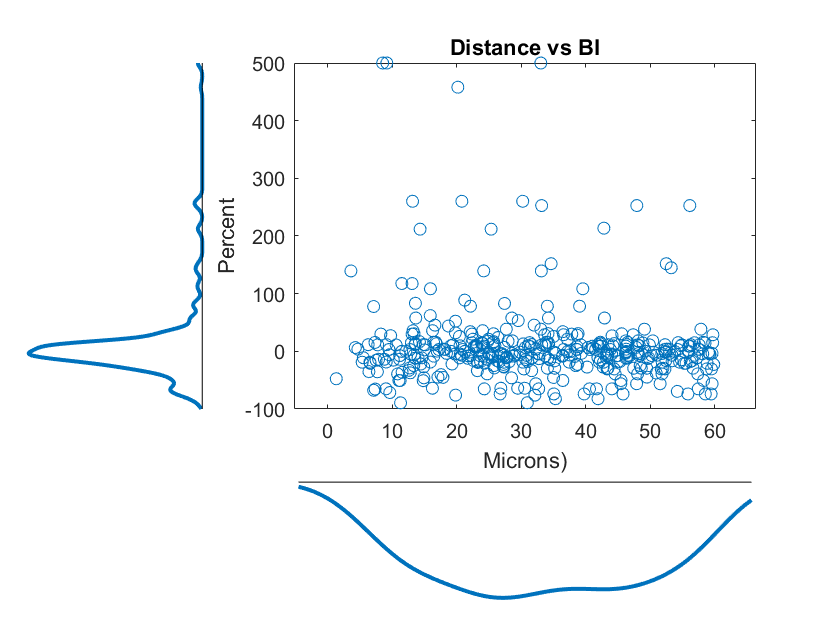


% distance vs BIchange
scatterhist(approxdata(:,7),approxdata(:,10), 'Kernel', 'on', 'Direction','out')
ylim([-100 500]);
% xlim([0 60])
xlabel('Microns)')
ylabel('Percent')
title('Distance vs BI')

save(strcat(outfolder,'\','approxdata.mat'),'approxdata_legend','approxdata');

disp('done pairwise plotting ')

done pairwise plotting 


# 5: Isolate DREADD RGCs 

Almost there, bare with me. The GFP location, the spike locs within a 30/60 micron radius around the GFP location and the spike firing/burst index changes are now known. Now, I define "Full Match" and "Match" units. Full match: units within 30 microns and a change of firing rate or burst index change of > 50%; Match: units within 60 microns and a change of firing rate or burst index change of > 50%. Why a positive change? I used excitatory DREADDS, hence I expect a positive change of activity in RGCs. NB we have plenty of negative change in RGCs (see figures above), potentially induced by DREADD ACs (see also immunohistochemistry figures in the manuscript) but they are not interesting for this paper (there will be another one, focussed only on these). Why 50%? I need a threshold and that 50% is based upon the figures above. Most of the percent change values are distributed gaussian-like between -100 and 100 % with decent amount of values higher than 100%. Looking at the figures above, 50% is in my oppinion a good cut-off, not too low and not too high. The next part selects the Full Match and Match units and stores their unit IDs for the SPIKE Distance calculation (next step) and classification. Further, the spike locs are plotted as an overlay over the GFP image . NB some units are close to more than one GFP structure and the smallest distance is selected. 

clearvars -except outfolder datafolder
load(strcat(outfolder,'\IHCaligned_data.mat'));
load(strcat(outfolder,'\goodunits.mat'));
load(strcat(outfolder,'\approxdata.mat'));

uniqueIDs = unique(approxdata(:,4));
uniqueIDs(uniqueIDs==0)=[];
k=1;
clearvars final_approxdata
for i = 1:length(uniqueIDs)
    clearvars idx tmp I
    idx = find(approxdata(:,4)==uniqueIDs(i));
    for ii = 1:length(idx)
        tmp(ii,1) = approxdata(idx(ii),4); % clus ID
        tmp(ii,2) = approxdata(idx(ii),7); % Distance
        tmp(ii,3) = approxdata(idx(ii),8); % MFR
        tmp(ii,4) = approxdata(idx(ii),10); % BI
        tmp(ii,5) = idx(ii);
    end
    if tmp(:,3)>50 | tmp(:,4)>50
        [~,I] = min(tmp(:,2));
        final_approxdata(k,:) = approxdata(idx(I),:);
        k=k+1;
    end
end
save(strcat(outfolder,'\','final_approxdata.mat'),'approxdata_legend','final_approxdata');

#### A: Plot GFP cell and spikes

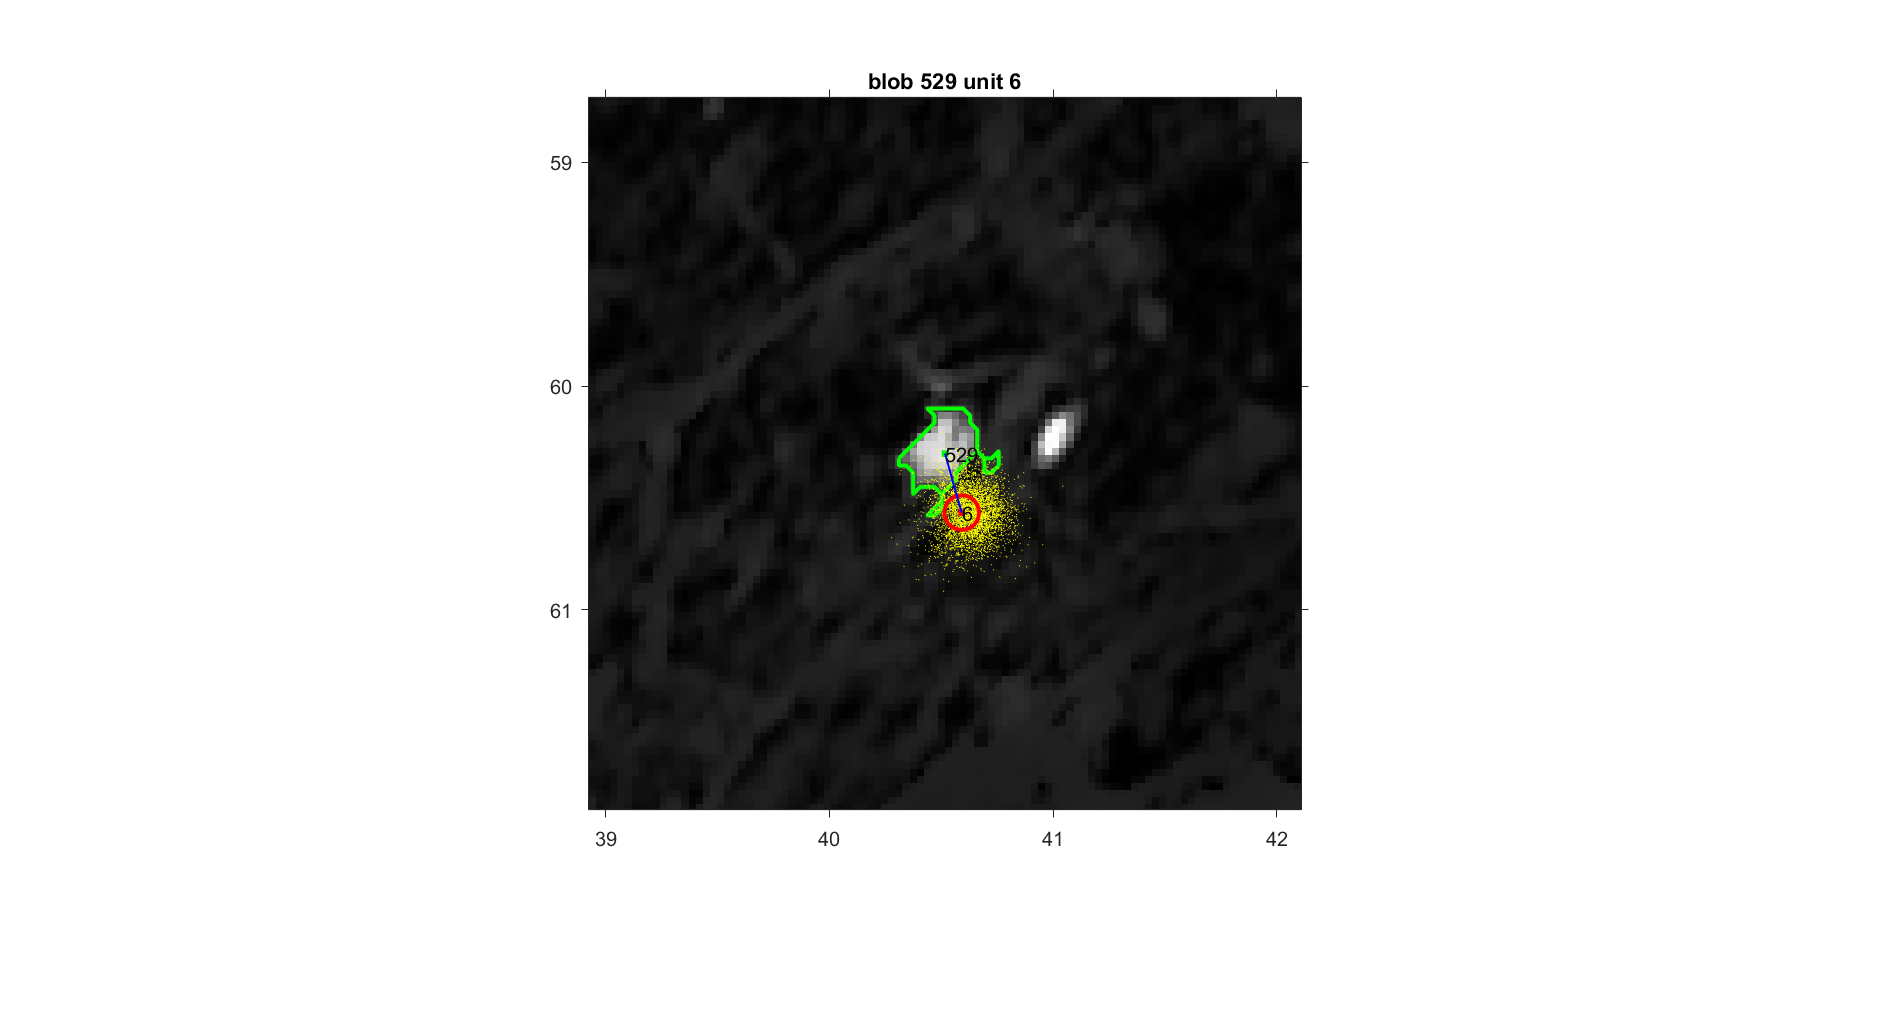

load(strcat(outfolder,'\GFPblob_data.mat'));
load(strcat(outfolder,'\blobstats.mat'));
% Herdingspikes 2 stores the spike information in Hdf5 files. Here you need to load the 
% hdf5 file with all spike locs (here spontaneous recording). 
sortedfile=strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_spont_ctl_clustered.hdf5'); 
cluster_id = double(h5read(sortedfile,'/cluster_id'));
spikedata = double(h5read(sortedfile,'/data'));
clus_centres = double(h5read(sortedfile,'/centres'))';
spikedata_IM = (spikedata*sf)+sf/2;
close(gcf)
% uncomment the line below (and at the end)
% when you want to plo ALL cells - otherwise mess is incoming
% set(0,'DefaultFigureVisible','off')
% for i = 1:length(final_approxdata(:,2))
for i = 1 % uncomment for all (see above)
    hFig=figure('units','normalized','outerposition',[0 0 1 1]);
    axes1 = axes('Parent',hFig,...
        'Position',[0.219023130868578 0.209401704243615 0.557840616966581 0.69551282051282]);
    
    imshow(GFPaligned(:,:,2),'Parent',axes1)
    hold(axes1,'on');
    thisBoundary = boundaries_GFP{final_approxdata(i,1)};
    plot(thisBoundary(:,2), thisBoundary(:,1), 'g', 'LineWidth', 2);
    hold(axes1,'on');
        
    clearvars xspikes yspikes
    xspikes = spikedata_IM(cluster_id==final_approxdata(i,4),2);
    yspikes = spikedata_IM(cluster_id==final_approxdata(i,4),1);
    scatter(xspikes,yspikes,1,'.','y','LineWidth',0.1)
    hold(axes1,'on');
    
    scatter(final_approxdata(i,5),final_approxdata(i,6),300,'o','r','LineWidth',2)
    hold(axes1,'on');
    scatter(final_approxdata(i,5),final_approxdata(i,6),100,'.','r','LineWidth',2)
    hold(axes1,'on');
    scatter(final_approxdata(i,2),final_approxdata(i,3),100,'.','g','LineWidth',2)
    hold(axes1,'on');
    plot([final_approxdata(i,5),final_approxdata(i,2)], [final_approxdata(i,6),final_approxdata(i,3)],'b','LineWidth',1)
    text(final_approxdata(i,5),final_approxdata(i,6),sprintf('%d',final_approxdata(i,4)))
     text(final_approxdata(i,2),final_approxdata(i,3),sprintf('%d',final_approxdata(i,1)))
    hold(axes1,'on');
    
    xticks(linspace(0,max(size(GFPaligned)),64))
    yticks(linspace(0,max(size(GFPaligned)),64))
    xticklabels(0:63)
    yticklabels(0:63)
        
    axis on
    axis square
    xlim([final_approxdata(i,2)-50, final_approxdata(i,2)+50])
    ylim([final_approxdata(i,3)-50 final_approxdata(i,3)+50])
    title(sprintf('blob %d unit %d',final_approxdata(i,1),final_approxdata(i,4)))

    saveas(gcf,strcat(outfolder,'\',(sprintf('blob_%d_unit_%d',final_approxdata(i,1),final_approxdata(i,4)))),'png');

end

% set(0,'DefaultFigureVisible','on')
disp('done plotting approximated units ')

done plotting approximated units 


# 6: Conclusion

At the end of this script you should have the unit IDs which are potential DREADD RGCs. In the next script, I will look closer at these cells and prepare them for SPIKE distance clusterng. So far, we only looked at sponatenous spiking, now it's time to chaneg that and look at light responses!